# Tema 5 - Integración Numèrica (III) 

### Matlab - Trapezis

Consulta la documentació i exemples de [trapz](https://es.mathworks.com/help/matlab/ref/trapz.html) i l'exemple de [integració de dades numèriques](https://es.mathworks.com/help/matlab/math/integration-of-numeric-data.html)

### Matlab - Romberg

Podeu fer ús dels codis de Matlab File Exchange, [codis](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) 

### Matlab - Integració adaptativa

%  quadgui(@(x)humps(x),0,1,1.0e-2)
integral(@(x)humps(x),0,1,'RelTol',1e-8,'AbsTol',1e-13)

### Fórmules de Newton- Côtes

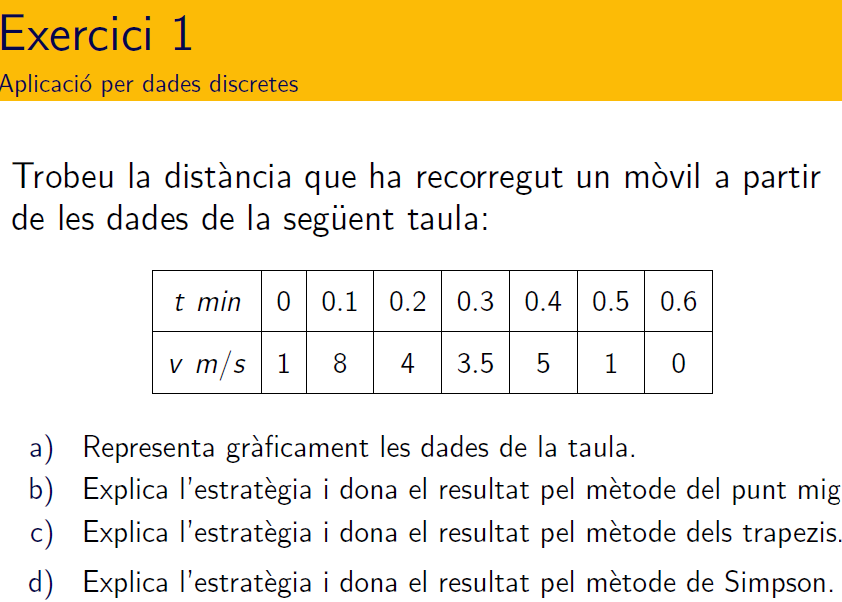

time =[0 0.1 0.2 0.3 0.4 0.5 0.6];

vel = [1 8 4 3.5 5 1 0];

plot(time,vel,'-*'), title('temps i velocitat mobil')
x= time*60;  % temps en segons
trapz(x,vel) % distancia total
cumtrapz(x,vel) % distancies principals

## Aplicam formules de teoria

Distancia calculada per la regla del punt mig

h = x(3)-x(1)
d = h*(vel(1)+vel(3)+vel(5))

Simpson

h= x(2)-x(1);
w = ones(size(vel));
w(2:2:end)=4; w(3:2:end-2)=2
d_S = sum(h/3*(w.*vel))

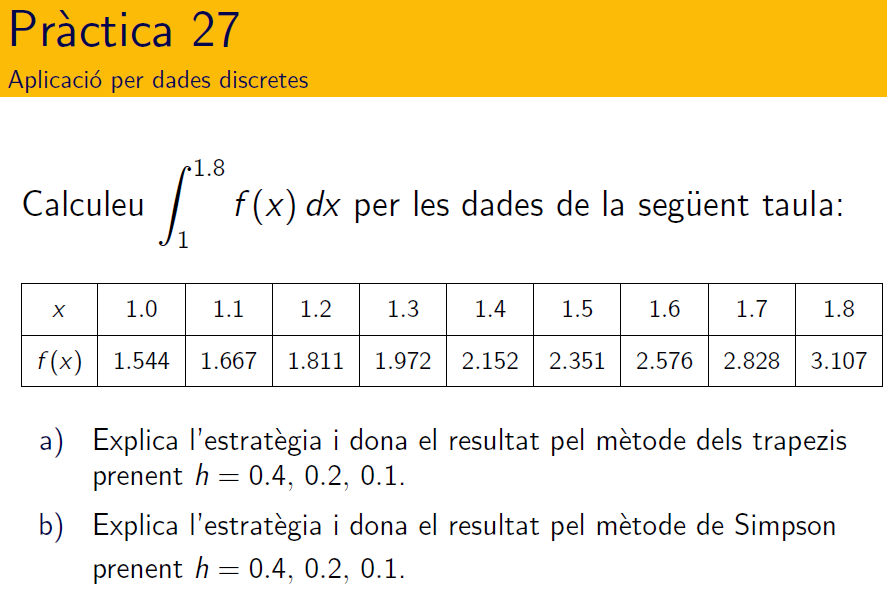

x =1.0:0.1:1.8;

y = [1.544 1.667 1.811 1.972 2.152 2.351 2.576 2.828 3.107];

% plot(x,y,'-*'), title('dades')
h = 0.4;
idx = @(t)1+t*h;

T = h/2* ( y(1) + 4*y(5) + y(9) )

T =        2.6518


S = h/3 * ( y(1) + 4*y(5) + y(9) )

S =        1.7679


#### h=0.1 Trapezi i simpson

T = trapz(x,y)

T =        1.7683



h = 0.1;
w= ones(size(y));
w(2:2:end)=4; w(3:2:end-2)=2;

w =      1     4     2     4     2     4     2     4     1


S = h/3 * sum(w.*y)

S =        1.7667


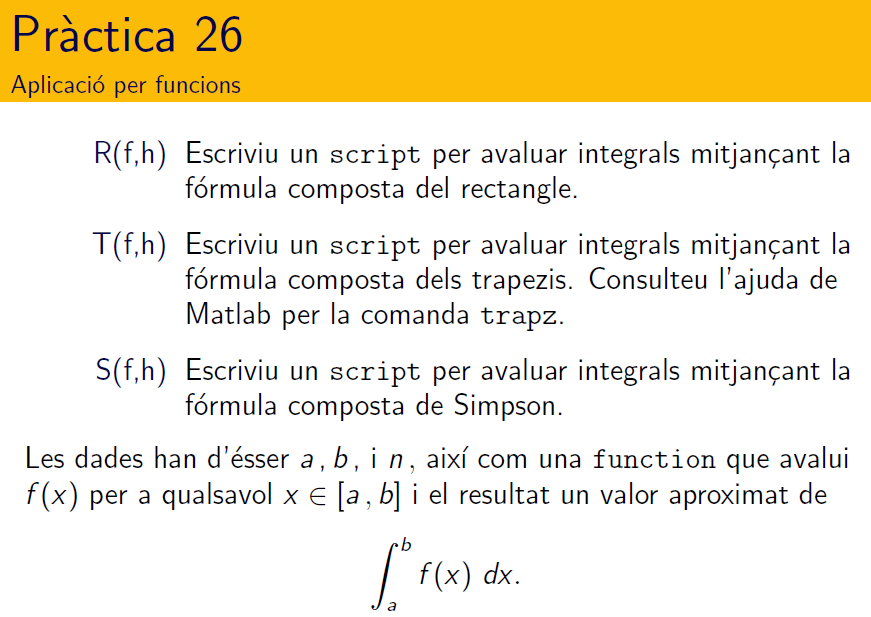

Verifiqueu els vostres codis amb el joc de proves de la pràctica 26. 

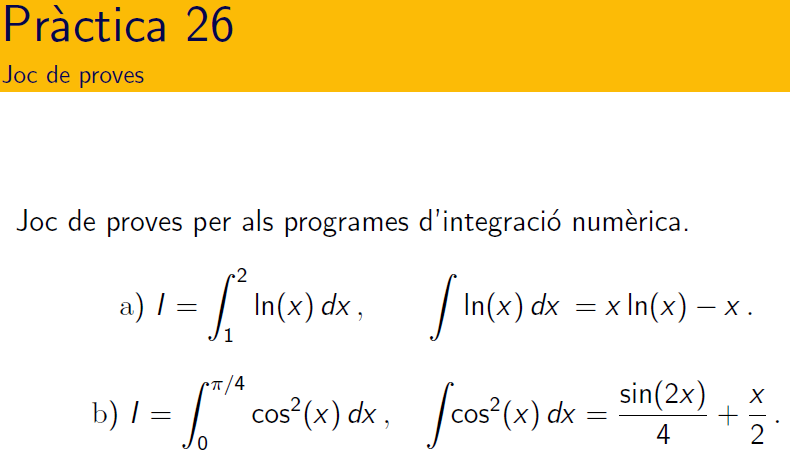

syms t
int(log(t),t)

$$ans = t\,\left(\log\left(t\right)-1\right)$$


ve= int(log(t),t,1,2), vec= double(ve)

$$ve = \log\left(4\right)-1$$

vec =       0.38629



h= 0.1; x = 1:h:2; y=log(x); T = trapz(x,y), abs(T-vec)

T =       0.38588


ans =    0.00041642


Roomberg


a           =   1;
b           =   2;
I           =   Romberg(@(x)log(x),a,b);

Unrecognized function or variable 'Romberg'.

fprintf('I\t=\t%0.15f\n',I);
abs(I-vec)

RombergDisp(@(x)log(x),a,b,3);

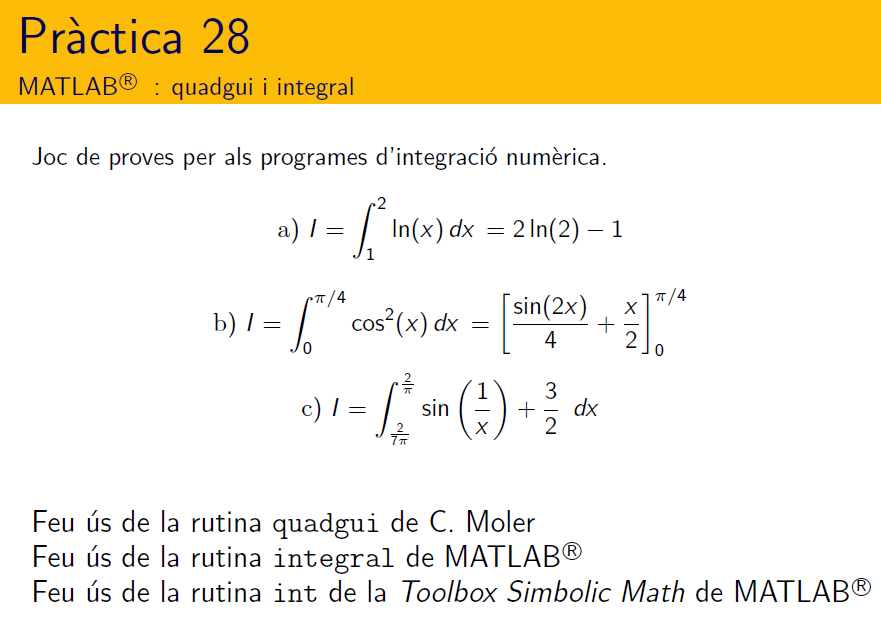

## Mètode de Romberg

JOC de PROVES

a) Calculeu el valor fent ús de punt mig

b) Calculeu el valor fent ús de trapezis

c) Apliqueu la taula d'extrapolació de romberg (podeu fer ús de [romberg.m](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) o un altre, verifiqueu el  vostre codi amb la taula següent)

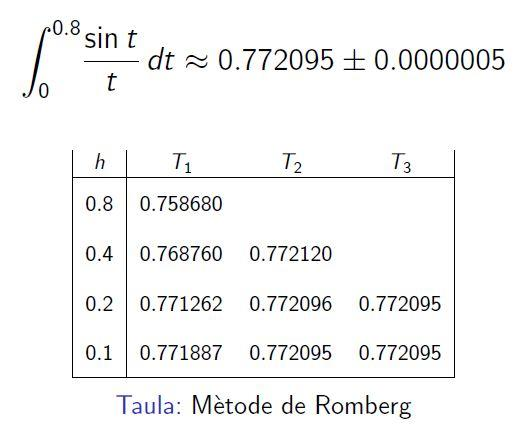

integral(@(x)log(x))

## Mètode de Montecarlo

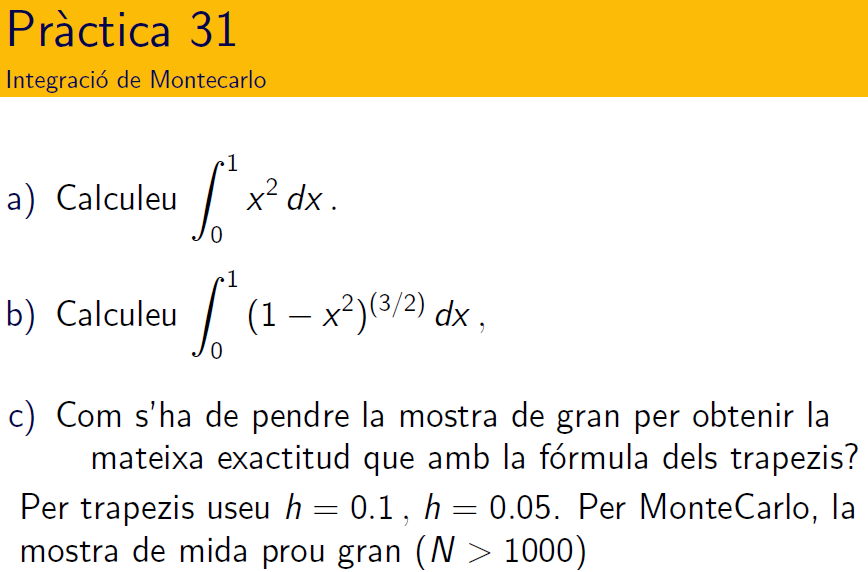

        
$$\quad a)\quad \int_0^1 x^2 dx = \frac{1}{3}$$
 

integral(@(x)x.^2,0,1)   % valor exacte